# Rasterising Exercises

Use the [modified Bresenham's algorithm](https://jonshiach.github.io/graphics-book/files/5.1_Drawing_lines.html?highlight=modified%20bresenham) to draw the lines joining points with the following co-ordinates:

(a) (2,2) and (7,5);

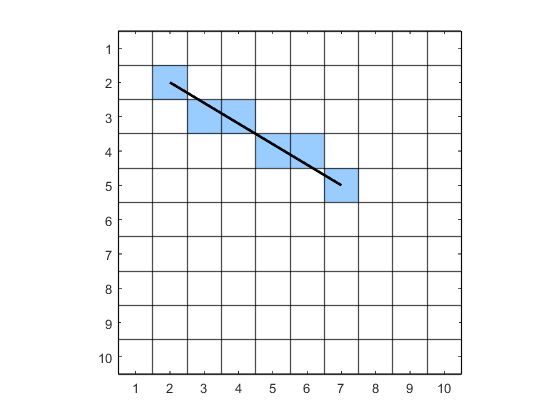

% Initialise raster array
Nx = 10;
Ny = 10;
img = 255 * ones(Ny, Nx, 3);

% Define endpoints
x0 = 2;
y0 = 2;
x1 = 7;
y1 = 5;
colour = [153 ; 204 ; 255] / 255;

% Draw line
img = drawline(img, x0, y0, x1, y1, colour);

% Plot raster
figure
image(img)
pixelgrid(img)
hold on
plot([x0, x1], [y0, y1], 'k', LineWidth=2)
hold off
axis equal tight
xticks(1:Nx)
exportgraphics(gcf,'../images/exercise_26a_sol.png', 'Resolution', 300)

(b) (8,3) and (5,8).

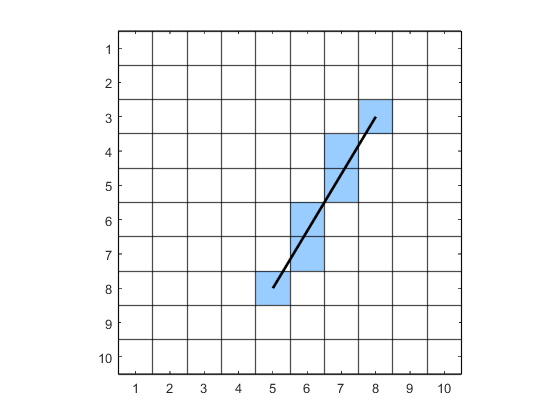

% Initialise raster array
Nx = 10;
Ny = 10;
img = 255 * ones(Ny, Nx, 3);

% Define endpoints
x0 = 8;
y0 = 3;
x1 = 5;
y1 = 8;
colour = [153 ; 204 ; 255] / 255;

% Draw line
img = drawline(img, x0, y0, x1, y1, colour);

% Plot raster
figure
image(img)
pixelgrid(img)
hold on
plot([x0, x1], [y0, y1], 'k', LineWidth=2)
hold off
axis equal tight
xticks(1:Nx)
exportgraphics(gcf,'../images/exercise_26b_sol.png', 'Resolution', 300)

### Exercise 27

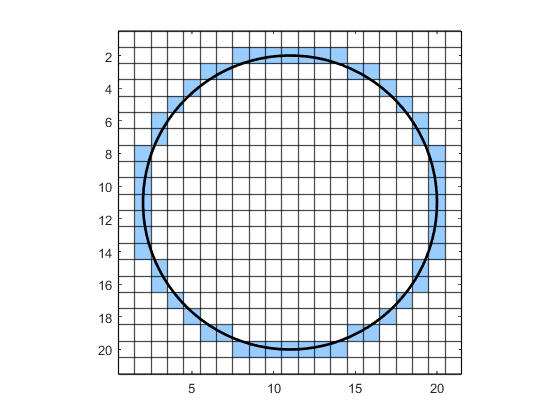

clear

% Define circle
cx = 11;
cy = 11;
r = 9;
colour = [153 ; 204 ; 255] / 255;

% Initialise raster array
Nx = 21;
Ny = 21;
img = 255 * ones(Ny, Nx, 3);

% Draw line
img = drawcircle(img, cx, cy, r, colour);

% Calculate circle
theta = linspace(0, 2 * pi, 100);
x = cx + r * cos(theta);
y = cy + r * sin(theta);

% Plot raster
figure
image(img)
pixelgrid(img)
hold on
plot(x, y, 'k', LineWidth=2)
hold off
axis equal tight

## Functions

Function to plot a grid of lines for the pixels

function pixelgrid(img)

[Ny, Nx, ~] = size(img);
for i = 1 : Ny + 1
    yline(i-0.5, Color='k', LineWidth=1)
end
for i = 1 : Nx + 1
    xline(i-0.5, Color='k', LineWidth=1)
end

end

### Bresenham's algorithm

function R = drawline(R, x0, y0, x1, y1, colour)

x = x0;
y = y0;
dx = abs(x1 - x0);
dy = abs(y1 - y0);
d = 2 * dx - 2 * dy;
xstep = 1;
ystep = 1;
if x > x1
    xstep = -1;
end
if y > y1
    ystep = -1;
end

while true
    R(y, x, :) = colour;
    if x == x1 && y == y1
        return
    end

    dd = 0;
    if d >= -dy
        x = x + xstep;
        dd = dd - 2 * dy;
    end
    
    if d <= dx
        y = y + ystep;
        dd = dd + 2 * dx;
    end
    d = d + dd;
end

end

### Midpoint algorithm

function R = drawcircle(R, cx, cy, r, colour)

x = r;
y = 0;
d = 1 - r;
while x >= y
    R(cx + x,cy + y, :) = colour;
    R(cx + x,cy - y, :) = colour;
    R(cx - x,cy + y, :) = colour;
    R(cx - x,cy - y, :) = colour;
    R(cx + y,cy + x, :) = colour;
    R(cx + y,cy - x, :) = colour;
    R(cx - y,cy + x, :) = colour;
    R(cx - y,cy - x, :) = colour;

    if d <= 0
        d = d + 2 * y + 3;
    else
        d = d + 2 * y - 2 * x + 5;
        x = x - 1;
    end
    y = y + 1;
end

end